## Problem 1

clear; clc;

syms x

f(x) = x*cos(x) - x^2*sin(x)

$$f(x) = x\,\cos\left(x\right)-x^{2}\,\sin\left(x\right)$$

f_prime(x) = diff(f,3)

$$f\_prime(x) = x^{2}\,\cos\left(x\right)-9\,\cos\left(x\right)+7\,x\,\sin\left(x\right)$$

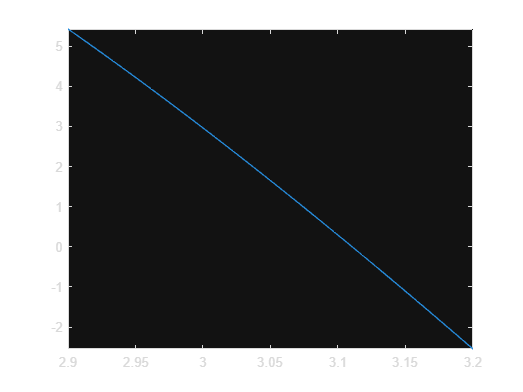

fplot(f_prime)
xlim([2.9, 3.2])


approx1 = 1/(2*0.1)*(-3*-4.827866 + 4*-4.240058 - -3.496909)

approx1 = 5.1014

approx2 = 1/(2*0.1)*(-3.496909 - -4.827866)

approx2 = 6.6548

approx3 = 1/(2*0.1)*(-2.596792 - -4.240058)

approx3 = 8.2163

approx4 = 1/(2*0.1)*(-4.240058 - 4*-3.496909 + 3*-2.596792)

approx4 = 9.7860


0.1^2/3*f_prime(2.9)

$$ans = 0.0181$$

0.1^2/6*f_prime(2.9)

$$ans = 0.0090$$

0.1^2/6*f_prime(3)

$$ans = 0.0049$$

0.1^2/3*f_prime(3)

$$ans = 0.0099$$


f_prime(x) = diff(f,1)

$$f\_prime(x) = \cos\left(x\right)-x^{2}\,\cos\left(x\right)-3\,x\,\sin\left(x\right)$$

abs(approx1 - f_prime(2.9))

$$ans = 0.0120$$

abs(approx2 - f_prime(3))

$$ans = 0.0049$$

abs(approx3 - f_prime(3.1))

$$ans = 4.7652e-04$$

abs(approx4 - f_prime(3.2))

$$ans = 0.0014$$

## Problem 2 (29)

clear; clc;

syms h epsilon M

e(h) = epsilon/h + h^2/6*M

$$e(h) = 0.1667\,M\,h^{2}+\frac{\epsilon }{h}$$

diff(e, h)

$$ans(h) = 0.3333\,M\,h-\frac{\epsilon }{h^{2}}$$

## Problem 3 (15c)

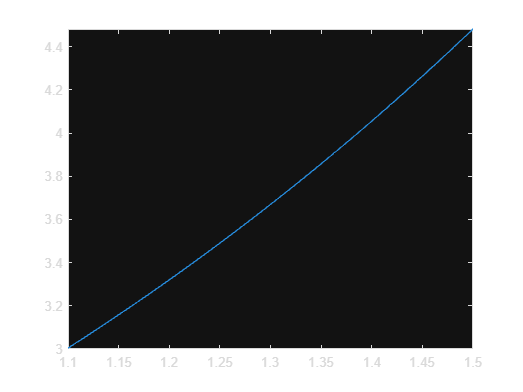

clear; clc;
format longg

syms x

f(x) = exp(x);
lim = [1.1 1.5];

fplot(f)
xlim(lim)


approx = zeros(8,1);
error = zeros(8,1);

n = 1;
h = (lim(2) - lim(1))/n;
points = linspace(lim(1), lim(2), n+1);
approx(n) = h/2*(f(points(1)) + f(points(2)));
error(n) = h^3/12*f(lim(end));

n = 2;
h = (lim(2) - lim(1))/n;
points = linspace(lim(1), lim(2), n+1);
approx(n) = h/3*(f(points(1)) + 4*f(points(2)) + f(points(3)));
error(n) = h^5/90*f(lim(end));

n = 3;
h = (lim(2) - lim(1))/n;
points = linspace(lim(1), lim(2), n+1);
approx(n) = 3*h/8*(f(points(1)) + 3*f(points(2)) + 3*f(points(3)) + f(points(4)));
error(n) = 3*h^5/80*f(lim(end));

n = 4;
h = (lim(2) - lim(1))/n;
points = linspace(lim(1), lim(2), n+1);
approx(n) = 2*h/45*(7*f(points(1)) + 32*f(points(2)) + 12*f(points(3)) + 32*f(points(4)) + 7*f(points(5)));
error(n) = 8*h^7/945*f(lim(end));

n = 0;
h = (lim(2) - lim(1))/(n+2);
points = linspace(lim(1), lim(2), n+3);
points = points(2:end-1);
approx(n + 5) = 2*h*f(points(1));
error(n + 5) = h^3/3*f(lim(end));

n = 1;
h = (lim(2) - lim(1))/(n+2);
points = linspace(lim(1), lim(2), n+3);
points = points(2:end-1);
approx(n + 5) = 3*h/2*(f(points(1)) + f(points(2)));
error(n + 5) = 3*h^3/4*f(lim(end));

n = 2;
h = (lim(2) - lim(1))/(n+2);
points = linspace(lim(1), lim(2), n+3);
points = points(2:end-1);
approx(n + 5) = 4*h/3*(2*f(points(1)) - f(points(2)) + 2*f(points(3)));
error(n + 5) = 14*h^5/45*f(lim(end));

n = 3;
h = (lim(2) - lim(1))/(n+2);
points = linspace(lim(1), lim(2), n+3);
points = points(2:end-1);
approx(n + 5) = 5*h/24*(11*f(points(1)) + f(points(2)) + f(points(3)) + 11*f(points(4)));
error(n + 5) = 95*h^5/144*f(lim(end));

actual_error = abs(int(f, lim(1), lim(2)) - approx);

double(approx)

ans =            1.4971710188569
          1.47753611765077
          1.47752885891182
          1.47752304950232
           1.4677186670477
          1.47098147226346
          1.47751161487243
          1.47751510112139


double(error)

ans =         0.0239023417084697
      1.59348944723131e-05
      7.08217532102805e-06
      3.79402249340788e-09
        0.0119511708542348
       0.00796744723615656
       1.3943032663274e-05
      9.68841583916637e-06


double(actual_error)

ans =         0.0196479724652679
      1.30712591333801e-05
      5.81252018924203e-06
      3.11068623168394e-09
       0.00980437934393411
       0.00654157412817039
       1.1431519205162e-05
      7.94527024142646e-06


## Problem 4 (13b)

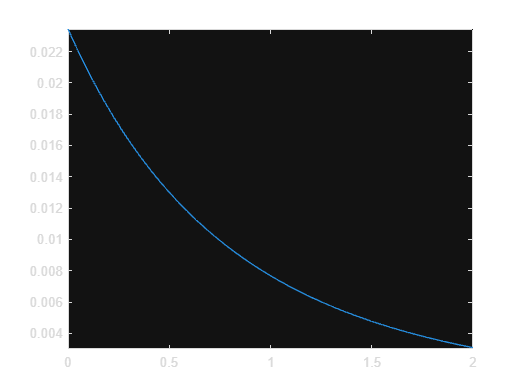

clear; clc;
format longg

syms x
f(x) = 1/(x+4);
f_prime4(x) = diff(f, 4);

fplot(f_prime4)
xlim([0 2])


(3.84e-2)^.25

ans =          0.442672767880129


2/(3.84e-2)^.25

ans =           4.51801001804922



double(compositeSimpson(f, 0, 2, 6))

ans =          0.405466374584022


## Problem 5 (1b, 3b)

clear; clc;

syms x
f(x) = x^2*exp(-x);
lim = [0, 1];

n = 2;
h = (lim(2) - lim(1))/n;
points = linspace(lim(1), lim(2), n+1);
approx(1) = h/3*(f(points(1)) + 4*f(points(2)) + f(points(3)));

n = 2;
h = (lim(2)/2 - lim(1))/n;
points = linspace(lim(1), lim(2)/2, n+1);
approx(2) = h/3*(f(points(1)) + 4*f(points(2)) + f(points(3)));

n = 2;
h = (lim(2) - lim(2)/2)/n;
points = linspace(lim(2)/2, lim(2), n+1);
approx(3) = h/3*(f(points(1)) + 4*f(points(2)) + f(points(3)));

double(approx')

ans =          0.162401683480679
        0.0288610717246675
          0.13186140414724



(1/15)*(approx(1) - approx(2) - approx(3))

$$ans = 1.1195e-04$$

approx(2) + approx(3)

$$ans = 0.1607$$

## Problem 7 (2a, 4a)

clear; clc;

syms x t

a = 0;
b = pi/4;

f(x) = exp(3*x)*sin(2*x);
real = int(f, a, b)

$$real = 2.5886$$


replace(t) = (1/2)*((b-a)*t + a + b);

approx2 = f(replace(0.5773502692))*(b - a)/2 + f(replace(-0.5773502692))*(b - a)/2;
approx3 = 5/9*f(replace(0.7745966692))*(b - a)/2 + 8/9*f(replace(0))*(b - a)/2 + 5/9*f(replace(-0.7745966692))*(b - a)/2;

double(approx2)

ans =           2.59132471568316


double(approx3)

ans =           2.58925800303196



error2 = double(abs(approx2 - real))

error2 =        0.00269608317598261


error3 = double(abs(approx3 - real))

error3 =       0.000629370524787804


## Problem 8 (1a)

clear; clc;

syms x y

a = 2.1;
b = 2.5;
c(x) = 1.2*x/x;
d(x) = 1.4*x/x;
f(x, y) = x*y^2;
n = 4;
m = 4;

double(doubleSimpson(a, b, m, n, c, d, f))

ans =          0.311573333333333
